% This is the distance matrix
d = distance_matrix(4)

d =          0    0.0625    0.0884    0.0625    0.1875    0.1976    0.1398    0.1768    0.2253    0.2652    0.1976    0.1398    0.1250    0.2500    0.2577    0.3187    0.3125    0.4375    0.4419    0.3802    0.3953    0.4550    0.4760    0.3644    0.3366    0.2795    0.4002    0.4419    0.4002    0.5039    0.5376    0.4881    0.5303    0.5762    0.6187    0.5376    0.4881    0.4507    0.5039    0.4550    0.3953    0.4193    0.3125    0.2795    0.3366    0.3187    0.2577    0.2500    0.3750    0.3802
    0.0625         0    0.0625    0.0884    0.1976    0.1875    0.1250    0.1398    0.1976    0.2253    0.1398    0.0884    0.0625    0.1875    0.1976    0.2577    0.2500    0.3750    0.3802    0.3187    0.3366    0.3953    0.4193    0.3125    0.2795    0.2253    0.3644    0.4002    0.3536    0.4507    0.4881    0.4419    0.4881    0.5303    0.5762    0.5039    0.4507    0.4193    0.4760    0.4419    0.3802    0.3953    0.2795    0.2577    0.3187    0.3125    0.2500    0.2577    0.3802    0


% Length of  distance matrix
n = length(d)

n = 206


% Calculate M = X * transpose(X)
% M = (m(i,j) for i,j = 1, ... n-1))


M = zeros(n, n)

M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


for i = 1:n
    for j = 1:n
        %M(i, j) = (d(1, j) ^ 2 - d(i, j) ^ 2 + d(i, 1) ^ 2)/2;
        M(i, j) = (d(i, n) ^ 2 - d(i, j) ^ 2 + d(j, n) ^ 2)/2;
    end
end


% [Q, T] = schur(M)
% T_ = [T(2, 2) 0; 0 T(4, 4)]
% Q_ = [Q(:, 2) Q(:, 4)]
% 
% X = Q_ *  T_ ^ (1/2)
% 
% plot(X(:,1), X(:, 2))

[U, S, V] = svd(M)

U =    -0.0640   -0.1599   -0.3566   -0.3210    0.0548   -0.0242    0.2177   -0.0781    0.3336    0.1320   -0.1005   -0.0053   -0.1372   -0.0894   -0.0483   -0.0504   -0.0096   -0.1226    0.4915   -0.4474    0.0964   -0.0331   -0.0459   -0.0508    0.0153    0.0389   -0.0081   -0.0189    0.0425    0.0119    0.0177    0.0123    0.0259    0.0165   -0.0033    0.0083   -0.0014   -0.0008    0.0238   -0.0229   -0.0308   -0.0254   -0.0228    0.0250    0.0421   -0.0025    0.0015    0.0312    0.0284   -0.0073
   -0.0597   -0.1492    0.3313    0.0708    0.4484   -0.0194    0.0440    0.0982   -0.1255    0.1697   -0.0866    0.0951   -0.2749   -0.0782   -0.1175    0.1017    0.1187    0.0366    0.0537   -0.0759   -0.1009    0.1568    0.1854    0.0836   -0.0719   -0.0100    0.0107    0.1106   -0.1199    0.0056    0.0750    0.1299    0.2390   -0.1765   -0.1534   -0.0647   -0.0737    0.0904    0.0442   -0.0693    0.0744    0.0773    0.0195   -0.0023    0.0319    0.0785    0.0444   -0.0196   -0.0076    0

S =   107.4043         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   17.1699         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

V =    -0.0640   -0.1599   -0.0138    0.0151   -0.0302    0.0236   -0.0150    0.0271   -0.0450    0.0197   -0.0521    0.0231   -0.0350    0.0486   -0.0211    0.0605         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0597   -0.1492    0.4596   -0.4036    0.5468   -0.2789    0.1163   -0.2257    0.2930   -0.0967    0.1971   -0.0660    0.0846   -0.0286    0.0727   -0.0087   -0.0157    0.0048   -0.0194    0.0270    0.0035   -0.0088    0.0017   -0.0083   -0.0207   -0.0102   -0.0034   -0.0028   -0.0121    0.0055   -0.0032    0.0006   -0.0038    0.0072    0.0127    0.0095    0.0049   -0.0039   -0.0098    0.0140   -0.0154   -0.0164   -0.0079    0.0013    0.0023    0.0030   -0.0030    0.0060    0.0060    0


index = find(diag(S) > 0.001)

index =      1
     2



X = U * sqrt(S)

X =    -0.6633   -0.6625   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
   -0.6191   -0.6184    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0


empty = []


empty =

     []




for i = 1:length(index)
    empty =[empty X(:, index(i))]
end

empty =    -0.6633
   -0.6191
   -0.6632
   -0.7075
   -0.7958
   -0.7516
   -0.7074
   -0.6632
   -0.7074
   -0.6631


empty =    -0.6633   -0.6625
   -0.6191   -0.6184
   -0.6632   -0.5741
   -0.7075   -0.6183
   -0.7958   -0.5299
   -0.7516   -0.4857
   -0.7074   -0.5299
   -0.6632   -0.4857
   -0.7074   -0.4415
   -0.6631   -0.3974


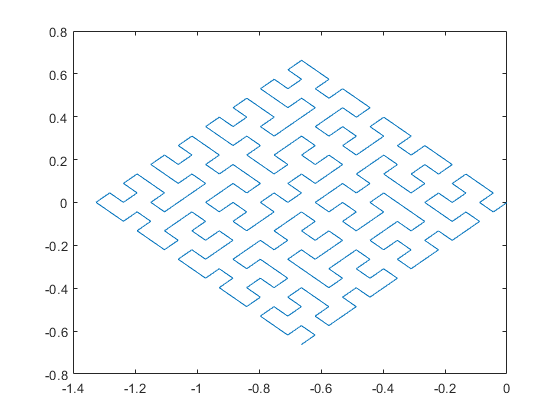

plot(X(:,1), X(:, 2))